data = readtable('logs/wins.csv');
data = table2array(data(:,1:4));
player_0 = data(:,1);
player_1= data(:,2);
player_2= data(:,3);
player_3= data(:,4);

data_mean = mean(data)

data_mean =    51.4500   16.6200   16.0200   15.9100


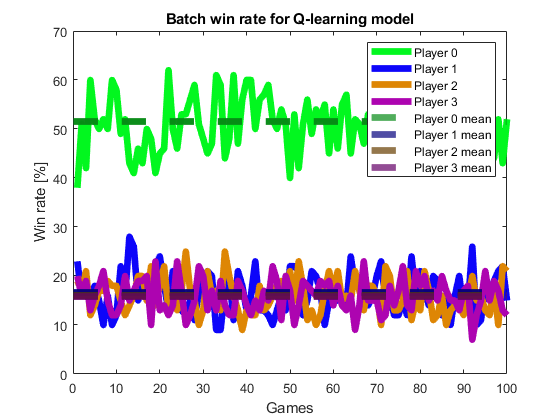

green = [2, 247, 31]/255;
green_mean = [6, 138, 21]/255;
blue = [13, 5, 250]/255;
blue_mean = [6, 2, 125]/255;
orange = [222, 134, 4]/255;
orange_mean = [102, 61, 0]/255;
purple = [173, 4, 176]/255;
purple_mean = [100, 0, 102]/255;

figure(1)
plot([1:length(data(:,1))],player_0,"color", green,"LineWidth",5)
hold on
plot([1:length(data(:,1))],player_1,"color", blue,"LineWidth",5)
plot([1:length(data(:,1))],player_2,"color", orange, "LineWidth",5)
plot([1:length(data(:,1))],player_3,"color", purple, "LineWidth",5)

yline(data_mean(1),'--',"Color",green_mean, "LineWidth",5)
yline(data_mean(2),'--',"Color",blue_mean,"LineWidth",5)
yline(data_mean(3),'--',"Color",orange_mean,"LineWidth",5)
yline(data_mean(4),'--',"Color",purple_mean,"LineWidth",5)

legend("Player 0","Player 1","Player 2", "Player 3", ...
    "Player 0 mean","Player 1 mean","Player 2 mean", "Player 3 mean")
xlabel("Games")
ylabel("Win rate [%]")
title("Batch win rate for Q-learning model")